# Choose the degree of the fitting polynomial

Answer: 6th degree polynomial

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\processed data");
addpath(fpath,dpath);
load 'processed data'\filtered_final\tableStruct4.mat

### Remove the data gathered by the first five sensors

As shown by the time cross-sectional animations of the original data, the temperature data gathered by the first five sensors is majorly influenced by the oil feed temperature.

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    t(:,2:6) = []; % remove col. 2 through 6
    tableStruct4(i).tableContents = t;
end

### Calculate the adjusted R^2 for all candidate polynomials & Store in separate field

To enhance the clarity of later visualizations, only the adj. R^2 for n = 30 uniformaly distributed time points are calculated.

Candidate Polynomials are the ones with even degrees (2, 4, 6, 8) to minimize deviation in the tail regions (symmetry)

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    tableStruct4(i).adjusted_R2 = adj_R2_polyfit(t,30,3:8); % n = 30
end
tableStruct4 % saved in

tableStruct4 = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate
    adjusted_R2


### Visualizations

data_10MPa_1.00h_Oil_20_deg_Stepped


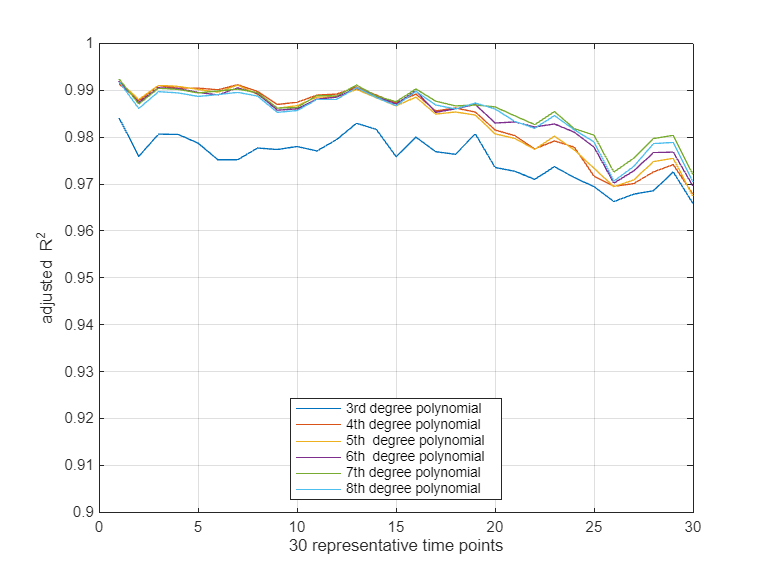

data_10MPa_1.00h_Oil_60_deg_Stepped


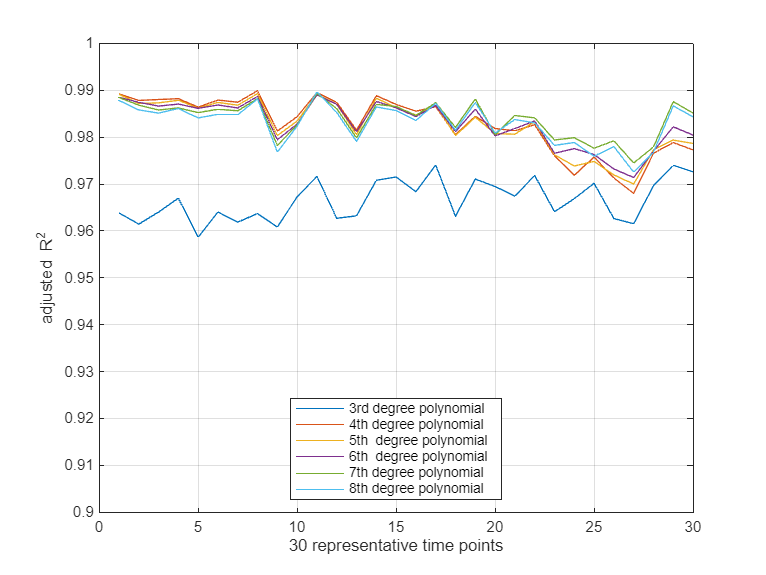

data_15MPa_1.00h_Oil_60_deg_Stepped


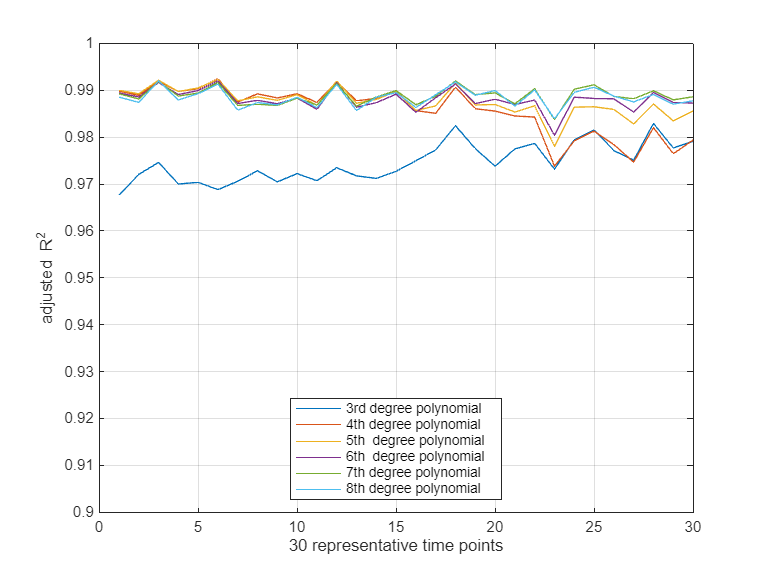

data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


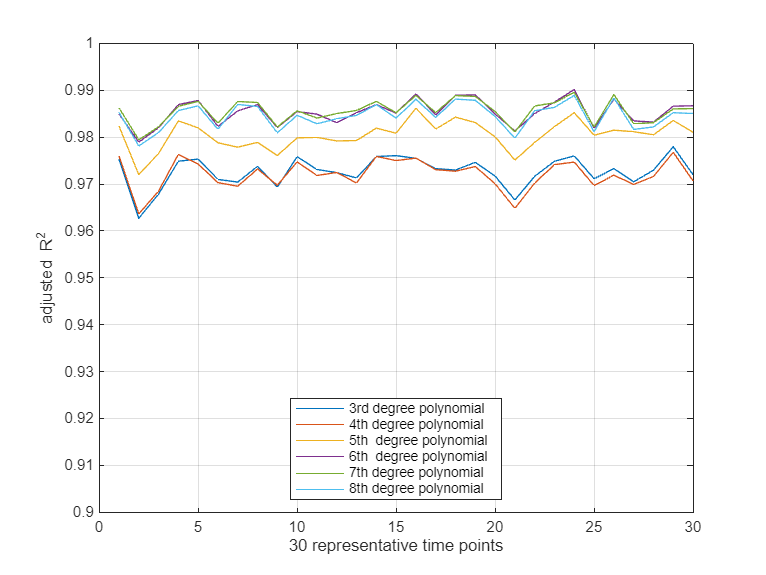

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    disp(t.Properties.Description);
    R2 = tableStruct4(i).adjusted_R2;

    % plot
    figure;
    plot(1:30,R2) % change along with the n in function adj_R2_polyfit!
    xlabel("30 representative time points"), ylabel("adjusted R^2")
    ylim([0.9,1]) % limit y range
    grid on
    legend("3rd degree polynomial","4th degree polynomial",...
        "5th  degree polynomial","6th  degree polynomial",...
        "7th degree polynomial","8th degree polynomial")
    legend("Location","south")

end

### Plot Δadj. R^2 between 6th degree and 4th degree polynomial

data_10MPa_1.00h_Oil_20_deg_Stepped


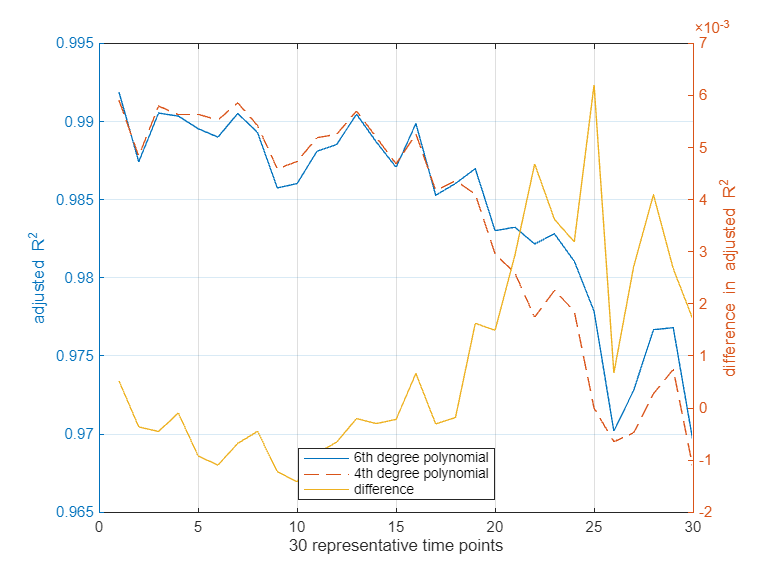

idx =     21    22    23    24    25    27    28    29


data_10MPa_1.00h_Oil_60_deg_Stepped


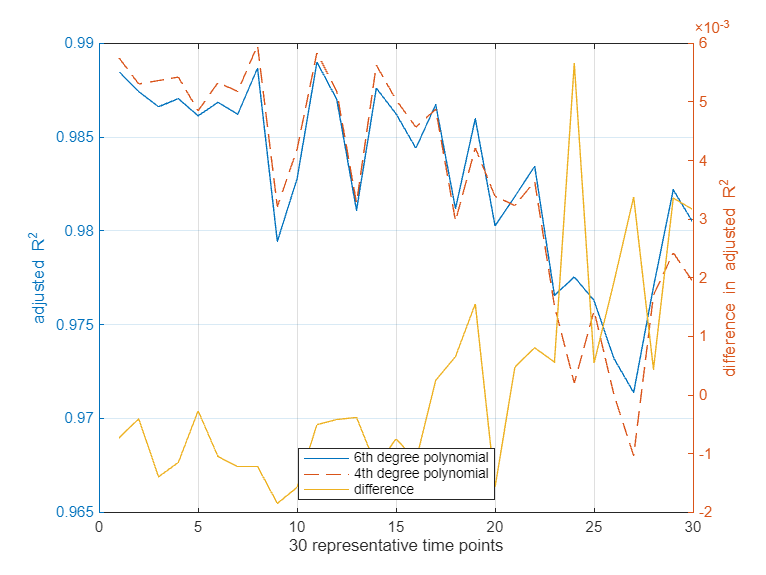

idx =     24    27    29    30


data_15MPa_1.00h_Oil_60_deg_Stepped


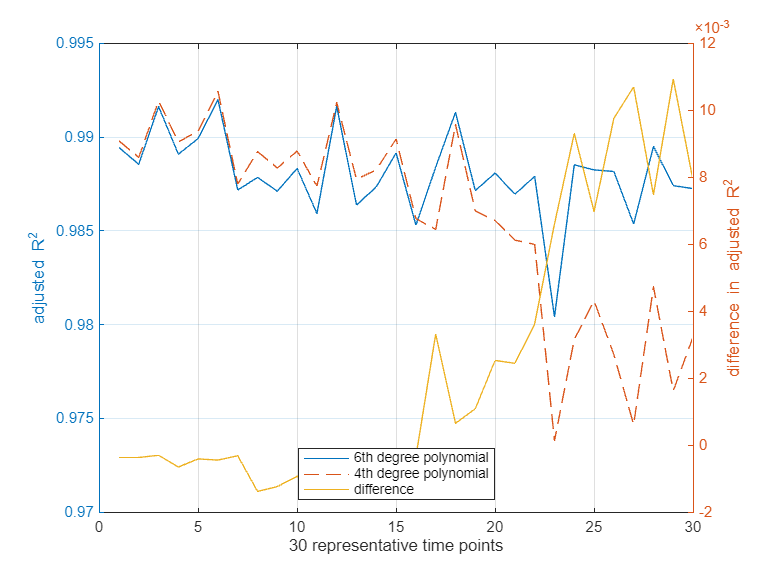

idx =     17    20    21    22    23    24    25    26    27    28    29    30


data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


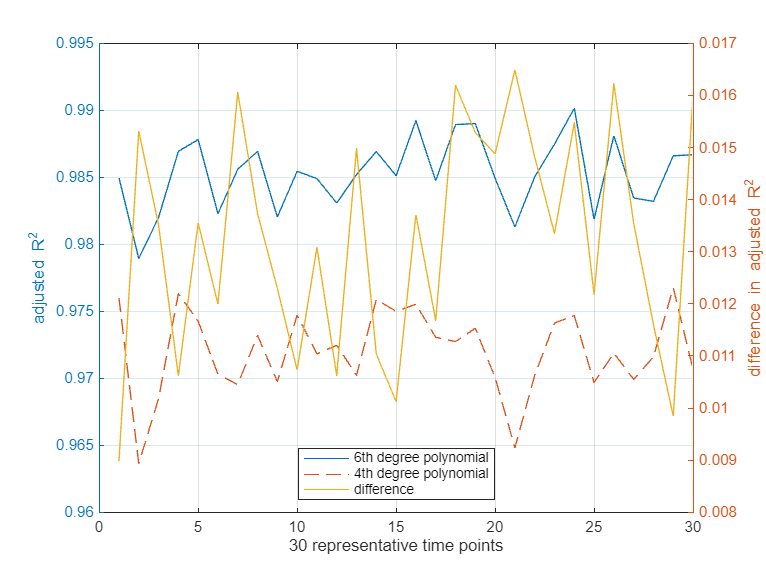

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    disp(t.Properties.Description);
    R2 = tableStruct4(i).adjusted_R2;
    dR2 = R2(4,:)-R2(2,:);

    figure;

    yyaxis left
    plot(1:30,R2(4,:),"Color",[0 0.4470 0.7410]) % change first argument along with n!
    ylabel("adjusted R^2")
    grid on, hold on
    plot(1:30,R2(2,:),"Color",[0.8500 0.3250 0.0980]) % change first argument along with n!
    hold off

    yyaxis right
    plot(1:30,dR2,"Color",[0.9290 0.6940 0.1250]) % change first argument along with n!
    ylabel("difference in adjusted R^2")

    xlabel("30 representative time points"), 
    legend("6th degree polynomial","4th degree polynomial","difference")
    legend("Location","south")    

    % to highlight
    idx = find(dR2>0.002)
end

### Above a certain So, 6th degree polynomial provides a better fit than 4th degree polynomial

Sommerfeld number So is calculated using v, p as well as η (calculated using T_en & measured T_max)

**Calculate So & Store in separate field**

load 'processed data'\tableStruct4_R2_added.mat
T_en = [20,60,60,60]; % oil feed temperature
psi = 1.16667/1000;
D = 120/1000; % [m]

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    num_rows = height(t);
    So_vector = zeros(num_rows,1);

    for j = 1:num_rows
        T_max = max(t{j,2:20}); % measured T_max

        if T_max >= T_en(i) % θ
            theta = T_max;
        else
            theta = T_en(i);
        end

        eta = viscosity(theta); % viscosity
        v = t{j,"Gleitgeschwindigkeit"}; % circumferential speed in [m/s]
        omega = 2*v/((1-psi)*D); % angular velocity in [1/s]
        p = t{j,"spez_Pressung"}*10^6; % specific pressure in [Pa]
        So = Sommerfeld(p,psi,eta,omega); % dimensionless
        So_vector(j) = So;
    end
    
    selected_rows = selectRows(t,30); % n = 30
    tableStruct4(i).So = So_vector(selected_rows,1);
end
tableStruct4

tableStruct4 = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate
    adjusted_R2
    So


**Concatenation and Plot**

Conclusion: When So ≥ 14, 6th degree polynomial can better describe the form of the temperature curve.

% concatenation
matrix1 = [tableStruct4(1).adjusted_R2;tableStruct4(1).So'];
matrix2 = [tableStruct4(2).adjusted_R2;tableStruct4(2).So'];
matrix3 = [tableStruct4(3).adjusted_R2;tableStruct4(3).So'];
matrix4 = [tableStruct4(4).adjusted_R2;tableStruct4(4).So'];
matrix = [matrix1,matrix2,matrix3,matrix4];
tbl = array2table(matrix',"VariableNames",["3","4","5","6","7","8","So"]);
head(tbl)

       3          4          5          6          7          8         So  
    _______    _______    _______    _______    _______    _______    ______

    0.98415    0.99137    0.99188    0.99189    0.99243    0.99186    2.8708
    0.97589    0.98778    0.98804    0.98742    0.98706    0.98611    3.0726
    0.98065    0.99099    0.99105    0.99054    0.99043     0.9897    3.1124
    0.98057    0.99044    0.99083    0.99035    0.99018    0.98943    3.1932
    0.97871    0.99046    0.99017    0.98954    0.98943    0.98868    3.2548
    0.97516     0.9901    0.98958      0.989    0.98985    0.98907    3.2755
    0.97519    0.99119     0.9911    0.99051    0.99023    0.98956    4.1466
    0.97767    0.98974    0.98911    0.98929    0.98948    0.98875  

tbl = sortrows(tbl,"So");

% plot
fig = tiledlayout(2,1,"TileSpacing","tight")

fig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 1]
            Padding: 'loose'
        TileSpacing: 'tight'

  Show all properties


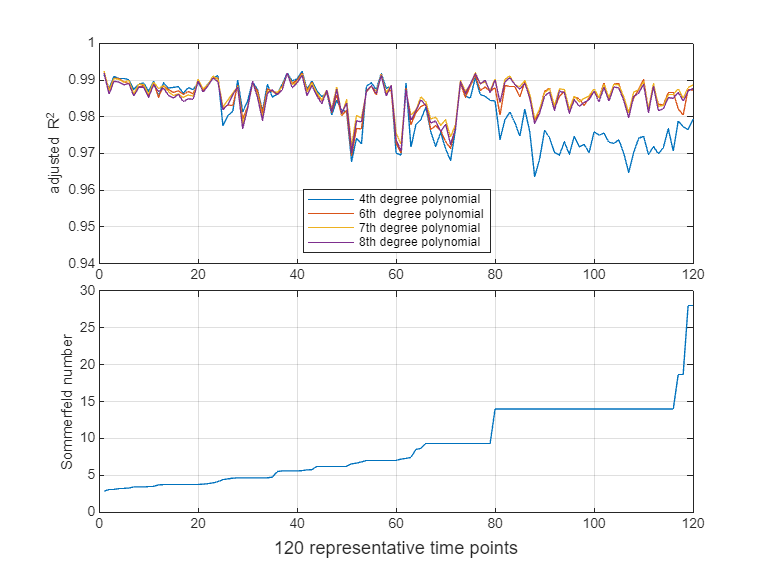

xlabel(fig,"120 representative time points")

ax1 = nexttile;
plot(1:height(tbl),tbl{:,[2,4,5,6]})
ylabel("adjusted R^2"), ylim([0.94,1])
legend("4th degree polynomial","6th  degree polynomial",...
        "7th degree polynomial","8th degree polynomial")
legend("Location","south"), grid on

ax2 = nexttile;
plot(1:height(tbl),tbl{:,"So"})
ylabel("Sommerfeld number")
grid on

linkaxes([ax1,ax2],'x')